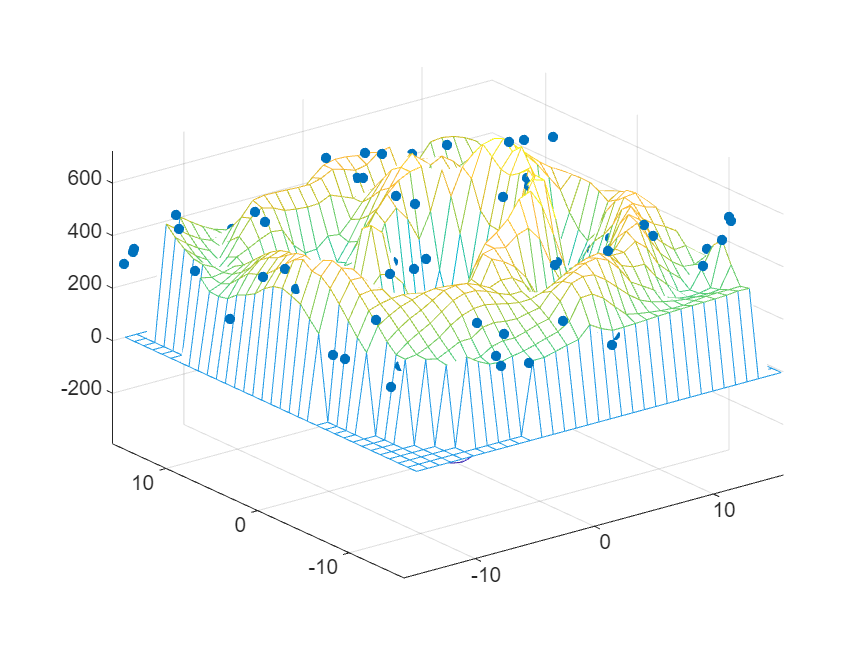

x = rand(100,1)*32 - 16;
y = rand(100,1)*32 - 16;
r = sqrt(x.^2 + y.^2) + eps;
z = (2000*cos(r)./r)+400;

xlin = linspace(min(x),max(x),33);
ylin = linspace(min(y),max(y),33);
%[X,Y] = meshgrid(xlin,ylin);

% Transpose x, y, and z to make them column vectors
%Z = griddata(x, y, z, X, Y, 'cubic');
somethin = mesh(X,Y,Z);
Z(isnan(Z))=0;

axis tight; hold on
plot3(x,y,z,'.','MarkerSize',15) 

%ax = gca;
%vrml(gcf, 'output.wrl')
XYZ=[X; Y; Z] 

XYZ =   -14.9219  -13.9652  -13.0085  -12.0518  -11.0951  -10.1384   -9.1817   -8.2250   -7.2683   -6.3117   -5.3550   -4.3983   -3.4416   -2.4849   -1.5282   -0.5715    0.3852    1.3419    2.2985    3.2552    4.2119    5.1686    6.1253    7.0820    8.0387    8.9954    9.9521   10.9088   11.8654   12.8221   13.7788   14.7355   15.6922
  -14.9219  -13.9652  -13.0085  -12.0518  -11.0951  -10.1384   -9.1817   -8.2250   -7.2683   -6.3117   -5.3550   -4.3983   -3.4416   -2.4849   -1.5282   -0.5715    0.3852    1.3419    2.2985    3.2552    4.2119    5.1686    6.1253    7.0820    8.0387    8.9954    9.9521   10.9088   11.8654   12.8221   13.7788   14.7355   15.6922
  -14.9219  -13.9652  -13.0085  -12.0518  -11.0951  -10.1384   -9.1817   -8.2250   -7.2683   -6.3117   -5.3550   -4.3983   -3.4416   -2.4849   -1.5282   -0.5715    0.3852    1.3419    2.2985    3.2552    4.2119    5.1686    6.1253    7.0820    8.0387    8.9954    9.9521   10.9088   11.8654   12.8221   13.7788   14.7355   15.6922
 

%make_STL_of_Array('mesh',XYZ, 10, 10, 10)  
%fig2u3d(gca, 'hi', 'none', 0)
